Clear the console and workspace

close all;
clear all;
clc;

**Import the following data:**

- Load Data (House in Paris)

- EDL Data (Boolean representing EDL On/Off)

- Solar Irradiance data

irradiance=importdata('solar_irradiance.csv',',')*1e-3; % NADIM DATA

Error using importdata
Unable to open file.

E_load=importdata('Load.csv',',')*1e-3; 
Temperature=importdata("Temperature.csv",",");
Temperature=reshape(Temperature,[366,24]);
EDL=importdata('EDL.csv',',');

Compute the power generated by PV using the following formula:

E (PV, DC) = Irradiance * Area * efficiency of panels

where:

- Area = 24 m^2 

- Efficiency = 22%

- a= 0.5%

A=24; % Area of the panels is 12 square meters
eff_pv_panel= 0.22; % efficiency of panels is 12%
E_pv_dc=irradiance.*A.*eff_pv_panel; 
NOCT=45;
a=0.5*1e-2;
T_cell=Temperature+(45-20)/0.8*1;
E_pv_dc=(1-a*(T_cell-25)).*E_pv_dc;

**Conversion efficiencies:**

- PV inverter efficiency = 97%

- Battery inverter efficiency = 94%

- Battery charging efficiency = 90%

- Battery discharging efficiency = 90%

eff_pv_inverter=0.97;%input(pv_inv_eff)/100;
eff_bat_inverter=0.94;%input(bat_inv_eff)/100;
Bat_eff_charging=0.9; % Efficieny of the Battery at Charging
Bat_eff_discharging=0.9; % Efficieny of the Battery at Disharging

**Battery Sizing and Characteristics:**

- Nominal Voltage = 12 V 

- Nominal Capacity = 2000Ah

V_bat_nominal=12; 
E_bat_nominal_Ah=2000;

Battery Nominal Capacity (KWh) = Nominal Capacity (Ah) * Nominal Voltage * 1e-3

E_bat_nominal_kWh=E_bat_nominal_Ah*V_bat_nominal*1e-3; % nominal battery capacity in kWh

**Charging Times of the battery:**

- minimum charging time = 5 h

- minimum discharging time = 5 h

%min_charging_time='Nominal time takes to fully charge the battery (hours):';
t_charging_min=5;%input(min_charging_time);
%min_discharging_time='Nominal time takes to fully discharge the battery (hours):';
t_discharging_min=5;%input(min_discharging_time);

Maximum Power of Battery = Nominal Capacity (KWh) / minimum charging time

Max_power_bat=E_bat_nominal_kWh/t_charging_min; % Maximum power of the battery

**Set the State of Charge limits:**

- Maximum State of Charge = 90%

- Minimum State of Charge = 30%

%min_SOC='Battery minimum state of charge (%):';
SOC_min=0.3;%input(min_SOC)/100;
SOC_max=0.9; % Maximum State of Charge

**Battery Parameters:**

- Self-Discharging Factor = 0.000035

- Aging Coefficient = 3e-4

- State of Health = 0 

a=0.000035;%input(self_discharging_factor);
Z_age_coeff=3e-4 ; % Battery ageing coefficient
SOHmin=0; % Minimum State of Health of the Battery

Time Step =  1 hour

delta_t=1; % Time interval is 1 hour........Hence, Power is numerically equal to Energy

PV Power (AC) = PV Power (DC) * PV inverter efficiency 

E_pv_ac=eff_pv_inverter.*E_pv_dc; % energy from PV at AC bus

**Initial Battery Conditions:**

- No Energy Transferred to/from Battery 

- SOC = 50%

- Nominal Battery Capacity in KWh

- Maximum Charging Rate = Energy Capacity / Minimum Charging Time

- Maximum Discharging Rate = Energy Capacity / Minimum Discharging Time

E_battery_DC(1,1)=0; % energy transfer to or from the battery at the beginning (at 0000h on 1st January)
SOC(1,1)=0.5;
E_bat_present_kWh(1,1)=E_bat_nominal_kWh*SOC(1,1);
E_bat_present_Ah(1,1)=E_bat_present_kWh(1,1)/(V_bat_nominal*1e-3);
charging_rate_max=E_bat_nominal_kWh/t_charging_min;
% maximum charging current (A)
discharging_rate_max=E_bat_nominal_kWh/t_discharging_min;
% maximum discharging current (A)

- Maximum energy input to battery (DC) = Nominal Voltage * Maximum Charging Rate 

- Maximum energy output from battery (DC) = Nominal Voltage * Maximum Discharging Rate 

if (E_bat_present_kWh(1,1)*(SOC(1,1)-SOC_min)>discharging_rate_max)
    E_batDC_Usable_kWh_discharge_hourly_max(1,1)=discharging_rate_max;
else
    E_batDC_Usable_kWh_discharge_hourly_max(1,1)=E_bat_present_kWh(1,1)*(SOC(1,1)-SOC_min); % maximum energy output from the battery in DC side per hour
end
if (E_bat_present_kWh(1,1)*(SOC_max-SOC(1,1))>charging_rate_max)
    E_batDC_Usable_kWh_charge_hourly_max(1,1)=charging_rate_max;
else
    E_batDC_Usable_kWh_charge_hourly_max(1,1)=E_bat_present_kWh(1,1)*(SOC_max-SOC(1,1)); % maximum energy input to the battery in DC side per hour
end


No initial capacity loss in the battery 

Hence, initial cumulative capacity loss = 0

Delta_E_bat(1,1)=0; % Intial Cumilative battery capacity loss

Assume the load is fully supplied by the grid at the beginning

E_grid=zeros(366,24);
E_grid(1,1)=E_load(1,1); % for plotting purposes 

Contribution of Battery in DC and AC

E_battery_DC=zeros(366,24);
E_battery_AC=zeros(366,24);

Create a variable to track the amount of load power met by PV

E_pv_total=zeros(366,24);

Create a variable to track the amount of load power met by PV

E_pv_supplied=zeros(366,24);

Create a variable to track the amount of load power met by battery

E_battery_supplied=zeros(366,24);

Create a variable to track the amount of load power met by the grid

E_grid_supplied=zeros(366,24);

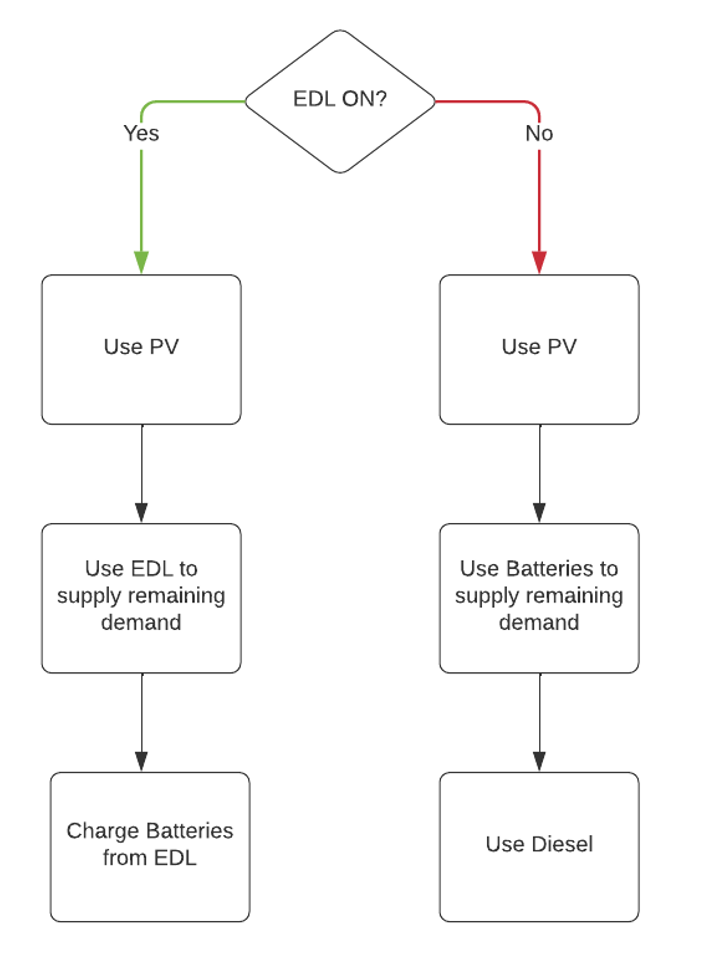

% ........... Energy flow simulation for a year....................................................
for day=1:366

 for t=1:24


If the grid is OFF, power supplied by the grid is surely 0. 

if EDL(day,t)==0
         E_grid(day,t)=0;
         E_grid_supplied(day,t)=0; % the difference between E_grid and E_grid_supplied is that the latter only focuses on the power supplied to the LOAD, while the former also includes batery charging


If the load can be met entirely by PV:

- Power supplied to load by PV = Power demanded by load

- If battery is not fully charged: charge as much as possible 

- If battery charged: No battery charge/discharge

The total power supplied by PV is the load power and the power needed to charge the battery. 

In this case, **PV and load powers appear. Battery charging may take place if not fully charged.**

  if E_pv_ac(day,t) >= E_load(day,t) 
             if SOC(day,t)< SOC_max %battery not fully charged 
                 if (E_pv_ac(day,t)-E_load(day,t))<(E_batDC_Usable_kWh_charge_hourly_max(day,t)/eff_bat_inverter) % not enough power to fully charge the battery
                     E_battery_AC(day,t)=(E_pv_ac(day,t)-E_load(day,t)); % battery charging
                     E_battery_DC(day,t)=E_battery_AC(day,t)*eff_bat_inverter;
                 else% (E_pv_ac(day,t)-E_load(day,t))>=(E_batDC_Usable_kWh_charge_hourly_max(day,t)/eff_bat_inverter); <=> % enough power to fully charge the battery
                     E_battery_DC(day,t)=E_batDC_Usable_kWh_charge_hourly_max(day,t); % battery charging
                     E_battery_AC(day,t)=E_battery_DC(day,t)/eff_bat_inverter;
                 end
             else %SOC(day,t)=SOC_max; % battery is fully charged 
                 E_battery_DC(day,t)=0;
                 E_battery_AC(day,t)=E_battery_DC(day,t)/eff_bat_inverter;
             end
             E_diesel(day,t)=0; % diesel generators are not used
             E_pv_supplied(day,t)=E_load(day,t); % load power met by PV 
             E_battery_supplied(day,t)=0; % battery is supplying no power to load
             E_pv_total(day,t)=E_pv_supplied(day,t)+E_battery_DC(day,t);


If load can NOT be met entirely by PV:

- If the battery is not at the minimum discharge level, have batteries supply as much power to load as possible, and use diesel if needed. 

- If the battery is at the minimum discharge level, use diesel to supply the remaining load demand, which was unmet by PV 

In this case, **PV, load & battery and/or diesel appear. **

  else %E_pv_ac(day,t) <= E_load(day,t); % if the load cannot be fully met by PV
             if SOC(day,t)>SOC_min % if the battery is not fully discharged
                 if (E_load(day,t)-E_pv_ac(day,t))<(E_batDC_Usable_kWh_discharge_hourly_max(day,t)*eff_bat_inverter) % if the remaining load can be met by the remaining power in battery
                    E_battery_AC(day,t)=-(E_load(day,t)-E_pv_ac(day,t)); % battery discharging
                    E_battery_DC(day,t)=E_battery_AC(day,t)/eff_bat_inverter;
                    E_diesel(day,t)=0;
                 else %(E_load(day,t)-E_pv_ac(day,t))>=(E_batDC_Usable_kWh_discharge_hourly_max(day,t)*eff_bat_inverter); % if the remaining load can NOT be met by the remaining power in battery
                    E_battery_DC(day,t)=-E_batDC_Usable_kWh_discharge_hourly_max(day,t); % battery discharging
                    E_battery_AC(day,t)=E_battery_DC(day,t)*eff_bat_inverter;
                    E_diesel(day,t)=E_load(day,t)-E_pv_ac(day,t)+E_battery_AC(day,t); % Energy from diesel after fully discharing the battery
                 end
             else %SOC(day,t)=SOC_min; % if battery is at the minimum discharge level, use diesel to support PV 
                 E_battery_DC(day,t)=0;
                 E_battery_AC(day,t)=eff_bat_inverter*E_battery_DC(day,t);
                 E_diesel(day,t)=E_load(day,t)-E_pv_ac(day,t);

             end
               E_pv_supplied(day,t)=E_pv_ac(day,t); % load power met partially by PV, this power is equal to the total available PV power 
               E_battery_supplied(day,t)=-E_battery_AC(day,t); % battery could be supplying power to the load if the discharged value is strictly less than zero 
  end


If the grid is ON, there is NO need for diesel generator support. 

  else %EDL(day,t)==1
         E_diesel(day,t)=0;


Since the grid is ON, the grid comes second in priority after PV. 

- If the power supplied by PV is sufficient to meet the load demand, all load power is met by PV. 

- If the power supplied by PV is insufficient to meet the load demand, the grid supplies the defficiency. 

In this case, **PV and load powers appear. Grid, if needed, can also appear. Batteries appear in charging mode only. **

if E_pv_ac(day,t) > E_load(day,t) % pv enough to fully meet load demand 
    E_pv_supplied(day,t)=E_load(day,t); % load completely met by PV 
else %E_pv_ac(day,t) < E_load(day,t) % if PV power sufficient, use only PV. Else, use grid to support PV. 
              E_grid(day,t)=E_load(day,t)-E_pv_ac(day,t); 
              E_grid_supplied(day,t)=E_load(day,t)-E_pv_ac(day,t);
              E_pv_supplied(day,t)=E_pv_ac(day,t);
end

This means that batteries will NOT be used to meet the load demand in this case. As a result, batteries will only CHARGE during this case. 

E_battery_supplied(day,t)=0;

- If the battery is fully charged, no charging or discharging takes place.

- If the battery is NOT fully charged, charge it as much as possible from PV and use the grid to charge the remaining amount. 

    if SOC(day,t)< SOC_max %if the battery is not fully charged 
                 if (E_pv_ac(day,t)-E_load(day,t))>=(E_batDC_Usable_kWh_charge_hourly_max(day,t)/eff_bat_inverter) %PV power is sufficient to entirely charge battery on its own
                     E_battery_DC(day,t)=E_batDC_Usable_kWh_charge_hourly_max(day,t); % battery charging
                     E_battery_AC(day,t)=E_battery_DC(day,t)/eff_bat_inverter;
                 else % (E_pv_ac(day,t)-E_load(day,t))<(E_batDC_Usable_kWh_charge_hourly_max(day,t)/eff_bat_inverter) %if PV can Not charge on its own the battery, use grid to charge remaining
                     %E_battery_AC(day,t)=(E_pv_ac(day,t)-E_load(day,t)); % battery charging
                     %E_battery_DC(day,t)=E_battery_AC(day,t)*eff_bat_inverter;
                     E_battery_DC(day,t)=E_batDC_Usable_kWh_charge_hourly_max(day,t); % battery charging
                     E_battery_AC(day,t)=E_battery_DC(day,t)/eff_bat_inverter;
                     E_grid(day,t)=E_grid(day,t)+E_batDC_Usable_kWh_charge_hourly_max(day,t)/eff_bat_inverter;
                 
                 end
    else %SOC(day,t)=SOC_max; %battery fully charged, no charging occurs 
                 E_battery_DC(day,t)=0;
                 E_battery_AC(day,t)=E_battery_DC(day,t)/eff_bat_inverter;
    end
end

**Battery State of Charge Update: **

  %------------------------------------ State of Charge(SOC) -----------------------------------------------------------------------------------
    if E_battery_DC(day,t)< 0
        SOC(day,t+1)= (SOC(day,t))-(abs(E_battery_DC(day,t))/(E_bat_nominal_kWh)); % battery discharging
    else
        SOC(day,t+1)= (SOC(day,t))+((abs(E_battery_DC(day,t)))/E_bat_nominal_kWh); % battery charging
    end
    E_bat_present_kWh(day,t+1)=E_bat_nominal_kWh*SOC(day,t+1) ;%Present Battery capacity
    E_bat_present_Ah(day,t+1)=(E_bat_present_kWh(day,t+1)/V_bat_nominal)*1e3;
    %----------------- Present Maximum Charging/Discharging rates---------------------------------------------------------------------
    %harging_rate_max(day,t+1)=E_bat_present_Ah(day,t+1)/t_charging_min;
    %discharging_rate_max(day,t+1)=E_bat_present_Ah(day,t+1)/t_discharging_min;
   if (E_bat_present_kWh(day,t+1)*(SOC(day,t+1)-SOC_min)>discharging_rate_max)
        E_batDC_Usable_kWh_discharge_hourly_max(day,t+1)=discharging_rate_max;
    else
        E_batDC_Usable_kWh_discharge_hourly_max(day,t+1)=E_bat_present_kWh(day,t+1)*(SOC(day,t+1)-SOC_min); % maximum energy output from the battery in DC side per hour
    end
    if (E_bat_present_kWh(day,t+1)*(SOC_max-SOC(day,t+1))>charging_rate_max)
        E_batDC_Usable_kWh_charge_hourly_max(day,t+1)=charging_rate_max;
    else
        E_batDC_Usable_kWh_charge_hourly_max(day,t+1)=E_bat_present_kWh(day,t+1)*(SOC_max-SOC(day,t+1)); % maximum energy input to the battery in DC side per hour
    end

    %----------------- Present stored Energy of the battery---------------------------------------------------------------------
    Energy_bat(day,t+1)=E_bat_present_kWh(day,t+1);
 end
E_bat_present_kWh(day+1,1)=E_bat_present_kWh(day,25);
E_batDC_Usable_kWh_charge_hourly_max(day+1,1)=E_batDC_Usable_kWh_charge_hourly_max(day,25);
E_batDC_Usable_kWh_discharge_hourly_max(day+1,1)=E_batDC_Usable_kWh_discharge_hourly_max(day,25);
SOC(day+1,1)=SOC(day,25);
Energy_bat(day+1,1)=Energy_bat(day,25);
end

Fix the State of Charge to a percentage 

SOC_percentage=SOC(1:366,1:24).*100; % SOC as a percentage

Change arrays to 1D for plotting 


% convert 2D data array to 1D array with number of elements 8784 for plotting
E_pv_ac_year=E_pv_ac(1,:);
E_load_year=E_load(1,:);
E_grid_year=E_grid(1,:);
E_diesel_year=E_diesel(1,:);
E_battery_year=E_battery_DC(1,:);
SOC_year=SOC_percentage(1,:);
Energy_bat_year=Energy_bat(1,1:24);
for i=2:366
    E_pv_ac_year=cat(2,E_pv_ac_year,E_pv_ac(i,:));
    E_load_year=cat(2,E_load_year,E_load(i,:));
    E_grid_year=cat(2,E_grid_year,E_grid(i,:));
    E_diesel_year=cat(2,E_diesel_year,E_diesel(i,:));
    E_battery_year=cat(2,E_battery_year,E_battery_DC(i,:));
    SOC_year=cat(2,SOC_year,SOC_percentage(i,:));
    Energy_bat_year=cat(2,Energy_bat_year,Energy_bat(i,1:24));
end

**Plot - Winter Day**


% plot data from start_hour to end_hour
start_hour=24*14;
end_hour=24*15;
plot((start_hour:end_hour)-start_hour,E_pv_ac_year(start_hour:end_hour),'b','linewidth',2.5);
grid on;
xlabel('Hour of the day(hr)','fontSize',11,'fontweight','bold');
ylabel('Power(kW)','fontSize',11,'fontweight','bold');
hold on;
plot((start_hour:end_hour)-start_hour,E_load_year(start_hour:end_hour),'r','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_grid_year(start_hour:end_hour),'g','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_battery_year(start_hour:end_hour),'black','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_diesel_year(start_hour:end_hour),'yellow','linewidth',2.5);
legend('E-pv','E-load','E-grid','E-battery-dc','E-diesel');

title('Energy Management System for a Winter Day')

legend('Position',[0.2193,0.67629,0.20893,0.19286])

**SOC Plot - Winter Day AW **

figure;
plot((start_hour:end_hour)-start_hour,SOC_year(start_hour:end_hour),'linewidth',2.5);
grid on;
xlabel('Hour of the day(hr)','fontSize',11,'fontweight','bold');
ylabel('State of Charge of the battery(%)','fontSize',11,'fontweight','bold'); 
title('State of Charge of the Battery during a Winter Day');

**Plot - Summer Day**

% plot data from start_hour to end_hour
start_hour=24*221;
end_hour=24*222;
plot((start_hour:end_hour)-start_hour,E_pv_ac_year(start_hour:end_hour),'b','linewidth',2.5);
grid on;
xlabel('Hour of the day(hr)','fontSize',11,'fontweight','bold');
ylabel('Power(kW)','fontSize',11,'fontweight','bold');
hold on;
plot((start_hour:end_hour)-start_hour,E_load_year(start_hour:end_hour),'r','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_grid_year(start_hour:end_hour),'g','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_battery_year(start_hour:end_hour),'black','linewidth',2.5);
hold on;
plot((start_hour:end_hour)-start_hour,E_diesel_year(start_hour:end_hour),'yellow','linewidth',2.5);
legend('E-pv','E-load','E-grid','E-battery-dc','E-diesel');

title('Energy Management System for a Winter Day')

xlim([0.0 25.0])
ylim([-5.00 5.00])
legend('Position',[0.4115,0.25551,0.20893,0.19286])
title('Energy Management System for a Summer Day')

**SOC Plot - Summer Day **

figure;
plot((start_hour:end_hour)-start_hour,SOC_year(start_hour:end_hour),'linewidth',2.5);
grid on;
xlabel('Hour of the day(hr)','fontSize',11,'fontweight','bold');
ylabel('State of Charge of the battery(%)','fontSize',11,'fontweight','bold'); 
title('State of Charge of the Battery during a Summer Day');

xlim([0.0 25.0])
ylim([25.0 100.0])

The remaining part is used to find the contribution of each source to the **LOAD** demand. 

The arrays are changed to 1 D for ease of use. 

E_pv_supplied_year=E_pv_supplied(1,:);
E_grid_supplied_year=E_grid_supplied(1,:);
E_battery_supplied_year=E_battery_supplied(1,:);
for i=2:366
    E_pv_supplied_year=cat(2,E_pv_supplied_year,E_pv_supplied(i,:));
    E_grid_supplied_year=cat(2,E_grid_supplied_year,E_grid_supplied(i,:));
    E_battery_supplied_year=cat(2,E_battery_supplied_year,E_battery_supplied(i,:));
end

Note that the diesel is only used to meet the load demand. It is NOT used to charge the batteries.

Create variables of similar names for diesel and load for ease of use. 

E_diesel_supplied_year=E_diesel_year;
E_load_demanded_year=E_load_year;

**Find the share of every source over the entire year:**

total_pv=sum(E_pv_supplied_year);
total_battery=sum(E_battery_supplied_year);
total_diesel=sum(E_diesel_year);
total_grid=sum(E_grid_supplied_year);
total_load_demand=sum(E_load_demanded_year);
percentage_pv=total_pv/total_load_demand*100;
percentage_battery=total_battery/total_load_demand*100;
percentage_diesel=total_diesel/total_load_demand*100;
percentage_grid=total_grid/total_load_demand*100;
pie([percentage_pv,percentage_battery,percentage_diesel,percentage_grid]);
title('Contribution of each source to the load demand')
legend({'PV','Battery','Diesel','Grid'})
legend('Position',[0.067619,0.75283,0.16071,0.15595])

legend({'PV','Battery','Diesel','EDL'})

**Load Characteristics **

maximum_load=max(E_load_year)
mininimum_load=min(E_load_year)
average_load=mean(E_load_year)
total_load=sum(E_load_year)*1e-3

**Load Profiles - Winter Day: 14 **

start_hour=14*24;
end_hour=15*24;
plot((start_hour:end_hour)-start_hour,E_load_year(start_hour:end_hour),'b','linewidth',2.5);

title('Load Profile during a Winter Day')
xlabel('Hour of the day (hr)')
ylabel('Power (kW)')

**Load Profiles - Summer Day: 221 **

start_hour=221*24;
end_hour=222*24;
plot((start_hour:end_hour)-start_hour,E_load_year(start_hour:end_hour),'b','linewidth',2.5);

title('Load Profile during a Summer Day')
xlabel('Hour of the day (hr)')
ylabel('Power (kW)')

**Grid Profile **

EDL=reshape(EDL,[8784,1]);
stem(1:72,EDL(1:72),".",'b')
xlabel("Time (hr)")
ylabel("EDL")
names={'OFF'; 'ON'};
set(gca,'ytick',[0 1],"yticklabel",names)
ylim([0.000 1.100])
title('EDL Modeling ')